**Modelling**

Import 3D Octomap and show the map model.

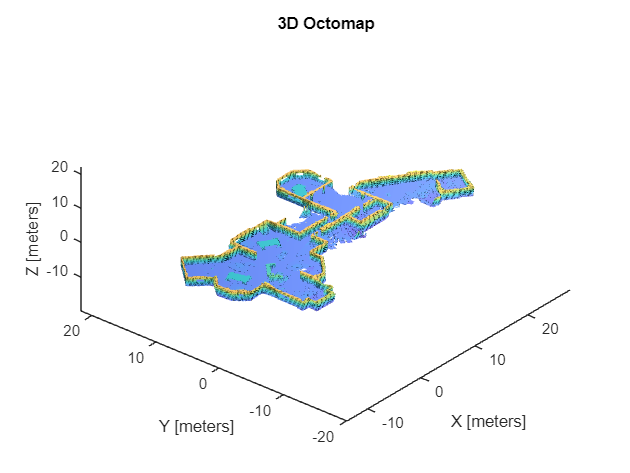

% Import the 3D occupancy map
map3D = importOccupancyMap3D("octomap_2.bt");
show(map3D);
title("3D Octomap");

Iterate each point (step size) in the occupancy point and store the occupied points.

% Define the step size
step_size = 0.1;
% Crop the map
x_offset = -14;
y_offset = -11;
x_max = 28;
y_max = 13;
z_min = -0.2;
z_max = 6;

% Define the threshold for consecutive unoccupied points
remove_floating = true;
if remove_floating
    max_consecutive_unoccupied = 10;
else
    max_consecutive_unoccupied = z_max/step_size; % Ignore floating points
end

% Define the ranges for x, y, and z
x_range = x_offset:step_size:x_max;
y_range = y_offset:step_size:y_max;
z_range = z_min:step_size:z_max;

% Preallocate arrays
x_len = length(x_range);
y_len = length(y_range);
z_len = length(z_range);

% Initialize the recordedPoints matrix to hold the highest z values for each (x, y) pair
Z = -inf(y_len, x_len);

% Iterate through x, y, z ranges
for i = 1:x_len
    for j = 1:y_len
        consecutive_unoccupied = 0; % Initialize counter for consecutive unoccupied points
        for k = 1:z_len
            occupancy = getOccupancy(map3D, [x_range(i), y_range(j), z_range(k)]);
            if occupancy > 0.65
                if z_range(k) > Z(j, i)
                    Z(j, i) = z_range(k);
                end
                consecutive_unoccupied = 0; % Reset counter if an occupied point is found
            else
                consecutive_unoccupied = consecutive_unoccupied + 1;
                if consecutive_unoccupied >= max_consecutive_unoccupied
                    break; % Skip the rest of the iteration in the z-direction
                end
            end
        end
    end
end

% Convert recorded points into a Digital Elevation Model (DEM)
[X, Y] = meshgrid(x_range, y_range);

% Set the floor value for Z where no occupancy was recorded above the threshold
Z(Z == -inf) = z_min;

Transform the 3D octomap into a DEM and visualise.

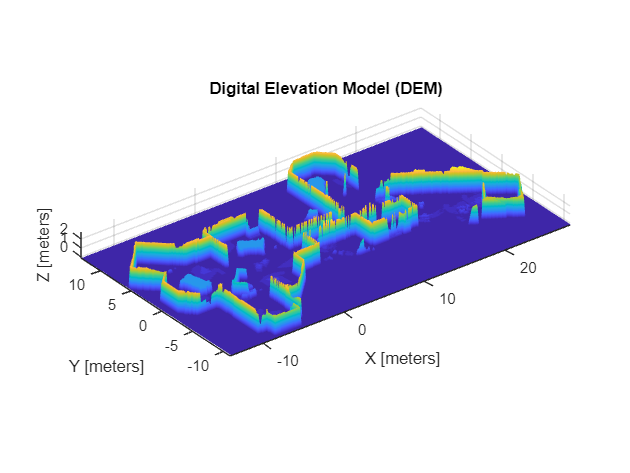

% Use surf for visualization
figure;
surf(X, Y, Z);
title('Digital Elevation Model (DEM)');
xlabel('X [meters]');
ylabel('Y [meters]');
zlabel('Z [meters]');
grid on;
axis equal;
shading interp; % Optional: makes the surface plot smoother